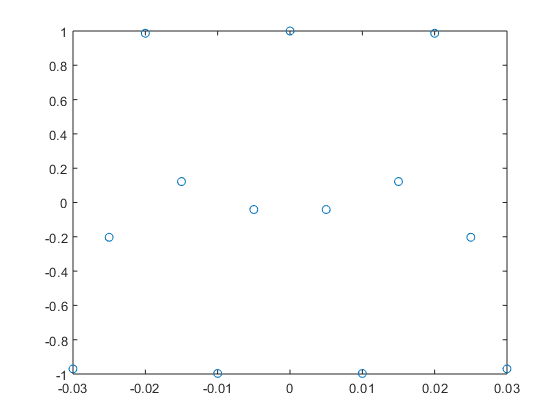

clear all
Fs = 200;
F0 = 50;
Fin = 51;
Foffset = .3;
Ain = 1;
AnalysisCycles = 3;

fitCrit = 1e-5;
maxIter = 50;   % maximum number of 4-parameter fit iterations
A = zeros(maxIter,1);
B = zeros(maxIter,1);

% time vector
duration = AnalysisCycles/F0;
t = -duration/2:1/Fs:duration/2;
Samples = Ain*cos(2*pi*(Fin+Foffset)*t);
plot(t,Samples,'o');

Create the model

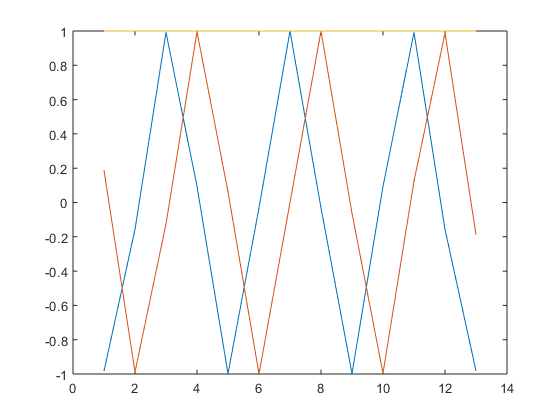

NSamples = size(Samples,2);
FundFreq = Fin;  %Initial guess at the frequency
tn = (-(NSamples/2-1/2):(NSamples/2-1/2))*1/Fs;
% model:
H = [cos(2*pi*FundFreq*tn)' sin(2*pi*FundFreq*tn)' ones(1,NSamples)'];
plot(H)

Traditional Least Squares Fit

S = (H'*H)\(H'*Samples');
A(1) = S(1); B(1) = S(2);
Ain = sqrt(A(1)^2+B(1)^2);
Theta = atan2(B(1),A(1));

Four Parameter Iterative Fit

Freq = Fin;  % first guess at frequency

for k = 1:maxIter
    H = [cos(2*pi*Freq*tn)' sin(2*pi*Freq*tn)' ones(1,NSamples)'];
    G = [H (-A(k)*tn.*sin(2*pi*Freq*tn) + B(k)*tn.*cos(2*pi*Freq*tn))'];
    S = (G'*G)\(G'*Samples');
    A(k+1) = S(1); B(k+1) = S(2);
    Ain = sqrt(A(k+1)^2+B(k+1)^2)
    Theta = atan2(B(k+1),A(k+1))
    dFreq(k) = S(size(S,1))/(2*pi)
    Freq = Freq + dFreq(k)
    ROCOF = dFreq(k)
    
    % check the residual
    if dFreq(k) < fitCrit
        break
    end
    
end

Ain = 0.9993

Theta = 3.8176e-18

dFreq = 0.3017

Freq = 51.3017

ROCOF = 0.3017

Ain = 1.0000

Theta = 3.7282e-19

dFreq =     0.3017   -0.0017


Freq = 51.3000

ROCOF = -0.0017